close all;
clear;
clc;


## Considerations

% It is necessary to create the following custom type to include any figure
% on a VHDL:
% TYPE ImageMatrix IS ARRAY (NATURAL RANGE <>, NATURAL RANGE <>) OF STD_logic_vector(7 DOWNTO 0);


## main code

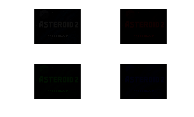



ImageName = 'start';

ImageFile = cat(2,ImageName,'.bmp');
TextFile  = cat(2,ImageName,'.txt');

RgbDecimalData = imread(ImageFile);
RgbDecimalData = bitshift(RgbDecimalData, -4);

ImageSize = size(RgbDecimalData);

ImageSizeX = ImageSize(2);
ImageSizeY = ImageSize(1);

RedDecimalData   = RgbDecimalData(:,:,1);
GreenDecimalData = RgbDecimalData(:,:,2);
BlueDecimalData  = RgbDecimalData(:,:,3);

EmptyLayer = 15*zeros(size(RedDecimalData,1),size(RedDecimalData,2));

figure(1)
subplot(2,2,1), imshow(RgbDecimalData)
subplot(2,2,2), imshow(cat(3,RedDecimalData,EmptyLayer,EmptyLayer))
subplot(2,2,3), imshow(cat(3,EmptyLayer,GreenDecimalData,EmptyLayer))
subplot(2,2,4), imshow(cat(3,EmptyLayer,EmptyLayer,BlueDecimalData))


NL = char(10);

Character9(1:ImageSizeY) = '(';
CharacterS(1:ImageSizeY) = ' ';
CharacterX(1:ImageSizeY) = 'x';
CharacterE(1:ImageSizeY) = char(34);
CharacterC(1:ImageSizeY) = ',';
Character0(1:ImageSizeY) = ')';
CharacterN(1:ImageSizeY) =  NL ;

HexDataR   = Character9';
HexDataG = Character9';
HexDataB  = Character9';

for i = 1:ImageSizeX
    
    for j = 1:ImageSizeY
        
        TempRedHexData   = dec2hex(RedDecimalData  (j,i));
        TempGreenHexData = dec2hex(GreenDecimalData(j,i));
        TempBlueHexData  = dec2hex(BlueDecimalData (j,i));
        
        if max(size(TempRedHexData)) == 1
  
        end
        
        if max(size(TempGreenHexData)) == 1
       
        end
        
        if max(size(TempBlueHexData)) == 1
         
        end
        
        if j == 1
            
            PrevRedHexData   = TempRedHexData;
            PrevGreenHexData = TempGreenHexData;
            PrevBlueHexData  = TempBlueHexData;
            
        else
            
            PrevRedHexData   = cat(1,PrevRedHexData  ,TempRedHexData);
            PrevGreenHexData = cat(1,PrevGreenHexData,TempGreenHexData);
            PrevBlueHexData  = cat(1,PrevBlueHexData ,TempBlueHexData);
            
        end
        
    end
    
    HexDataR = cat(2,HexDataR  ,CharacterS',CharacterX',CharacterE',PrevRedHexData  ,CharacterE',CharacterS');
    HexDataG = cat(2,HexDataG,CharacterS',CharacterX',CharacterE',PrevGreenHexData,CharacterE',CharacterS');
    HexDataB = cat(2,HexDataB ,CharacterS',CharacterX',CharacterE',PrevBlueHexData ,CharacterE',CharacterS');
    
    if i<ImageSizeX
        
        HexDataR = cat(2,HexDataR ,CharacterC');
        HexDataG = cat(2,HexDataG ,CharacterC');
        HexDataB = cat(2,HexDataB ,CharacterC');
        
    else
        
        HexDataR = cat(2,HexDataR ,Character0',CharacterC',CharacterN');
        HexDataG = cat(2,HexDataG ,Character0',CharacterC',CharacterN');
        HexDataB = cat(2,HexDataB ,Character0',CharacterC',CharacterN');
        
    end
end


HexDataR;
HexDataG;
HexDataB;

CharMatrix  = size(HexDataR);
CharMatrixX = CharMatrix(2);

ConstantLabel = "CONSTANT ";
MatrixLabel = strcat(" : ImageMatrix(0 TO ",string(ImageSizeX-1),...
                     ", 0 TO ",string(ImageSizeY-1),") := (");

MatrixNameR = strcat(ConstantLabel,ImageName,"R",MatrixLabel);
MatrixNameG = strcat(ConstantLabel,ImageName,"G",MatrixLabel);
MatrixNameB = strcat(ConstantLabel,ImageName,"B",MatrixLabel);

File = fopen(TextFile,'wb');
fwrite(File, MatrixNameR', 'char');
fwrite(File, NL          , 'char');
fwrite(File, HexDataR'   , 'char');
fwrite(File, ");"        , 'char');
fwrite(File, NL          , 'char');
fwrite(File, NL          , 'char');
fwrite(File, MatrixNameG', 'char');
fwrite(File, NL          , 'char');
fwrite(File, HexDataG'   , 'char');
fwrite(File, ");"        , 'char');
fwrite(File, NL          , 'char');
fwrite(File, NL          , 'char');
fwrite(File, MatrixNameB', 'char');
fwrite(File, NL          , 'char');
fwrite(File, HexDataB'   , 'char');
fwrite(File, ");"        , 'char');
fwrite(File, NL          , 'char');
fclose(File);

